## Privacy for Connected Vehicles

For this project, we used the the OBD-2 Datasets on Kaggle provided by Cephas Barreto. The datasets can be viewed and downloaded from this link: [OBD-II datasets | Kaggle](https://www.kaggle.com/datasets/cephasax/obdii-ds3?select=exp2_19drivers_1car_1route.csv)

The code and structure of this matlab script coincides with the Privacy for Connected Vehicles Research conducted by Brijesh Mishra, Vivek Pathak, Naveen Janarthanan, and Umesh Tanniru 

- Paper: [PrivacyForConnectedVehicles_ProjectFinalReport - Google Docs](https://docs.google.com/document/d/1C3ZuV3J04gM74kmVJLsF-kJJDNg6RuCwfVtR5IaKYrM/edit#)

- Presentation: [PrivacyforConnectedVehicles.pptx - Google Slides](https://docs.google.com/presentation/d/1ZUKDBom6ArLx8xU-tnh97Tugt9CCGH4g/edit#slide=id.g1240ab9aceb_0_1)

## Driving Behavior Data Privacy Optimization

From the proposed privacy dashboard, one of the privacy controls is the anonymization of driving behavior data. If the customer decides to toggle on the "Driving Behavior Data" button. The privacy algorithms will attempt to anonymize the dataset based on the following characteristics:

- **Identity:** VEHICLE_ID

- **Quasi-Identifiers**: MARK, MODEL, CAR_YEAR, ENGINE_POWER, AUTOMATIC, FUEL_TYPE

- **Sensitive Attributes**: FUEL_LEVEL, ENGINE_RPM, SPEED, ENGINE_RUNTIME, HOURS, DAYS_OF_WEEK, MONTHS, YEAR

% Driving Behavior

% Extract dataset variable names from
% 'exp1_14drivers_14cars_dailyRoutes.csv'
T_14D_14C_R = readtable("exp1_14drivers_14cars_dailyRoutes.csv",'VariableNamingRule','preserve');
all_attributes = T_14D_14C_R.Properties.VariableNames

all_attributes = 1×33 cell array
    {'TIMESTAMP'}    {'MARK'}    {'MODEL'}    {'CAR_YEAR'}    {'ENGINE_POWER'}    {'AUTOMATIC'}    {'VEHICLE_ID'}    {'BAROMETRIC_PRESSURE(KPA)'}    {'ENGINE_COOLANT_TEMP'}    {'FUEL_LEVEL'}    {'ENGINE_LOAD'}    {'AMBIENT_AIR_TEMP'}    {'ENGINE_RPM'}    {'INTAKE_MANIFOLD_PRESSURE'}    {'MAF'}    {'LONG TERM FUEL TRIM BANK 2'}    {'FUEL_TYPE'}    {'AIR_INTAKE_TEMP'}    {'FUEL_PRESSURE'}    {'SPEED'}    {'SHORT TERM FUEL TRIM BANK 2'}    {'SHORT TERM FUEL TRIM BANK 1'}    {'ENGINE_RUNTIME'}    {'THROTTLE_POS'}    {'DTC_NUMBER'}    {'TROUBLE_CODES'}    {'TIMING_ADVANCE'}    {'EQUIV_RATIO'}    {'MIN'}    {'HOURS'}    {'DAYS_OF_WEEK'}    {'MONTHS'}    {'YEAR'}


% Removing Blank Car Make
car_mark_to_remove = any(cellfun(@isempty, T_14D_14C_R.MARK), 2);
T_14D_14C_R(car_mark_to_remove,:) = [];

% TESTING PURPOSES
% vehicle_14_to_remove = ismember(T_14D_14C_R.VEHICLE_ID, 'car14');
% T_14D_14C_R(vehicle_14_to_remove,:) = [];

T_14D_14C_R.CAR_YEAR(isnan(T_14D_14C_R.CAR_YEAR)) = 0;
T_14D_14C_R.ENGINE_RUNTIME(isnan(T_14D_14C_R.ENGINE_RUNTIME)) = 0;
T_14D_14C_R.SPEED(isnan(T_14D_14C_R.SPEED)) = -1;
T_14D_14C_R.ENGINE_RPM(isnan(T_14D_14C_R.ENGINE_RPM)) = -1;
T_14D_14C_R.SPEED(isnan(T_14D_14C_R.SPEED)) = -1;
T_14D_14C_R.MIN(isnan(T_14D_14C_R.MIN)) = -1;
T_14D_14C_R.HOURS(isnan(T_14D_14C_R.HOURS)) = -1;
T_14D_14C_R.DAYS_OF_WEEK(isnan(T_14D_14C_R.DAYS_OF_WEEK)) = -1;
T_14D_14C_R.MONTHS(isnan(T_14D_14C_R.MONTHS)) = -1;
T_14D_14C_R.YEAR(isnan(T_14D_14C_R.YEAR)) = -1;

for s = 10:10:150
    T_14D_14C_R.SPEED(T_14D_14C_R.SPEED > (s-10) & T_14D_14C_R.SPEED < s) = s;
end
for m = 1:5:125
    T_14D_14C_R.ENGINE_RUNTIME(T_14D_14C_R.ENGINE_RUNTIME > duration(0,m-5,0) & T_14D_14C_R.ENGINE_RUNTIME < duration(0,m,0)) = duration(0,m,0);
end

for m = 400:100:3900
    T_14D_14C_R.ENGINE_RPM(T_14D_14C_R.ENGINE_RPM > m-100 & T_14D_14C_R.ENGINE_RPM < m) = m;
end

temp = zeros(size(T_14D_14C_R.FUEL_LEVEL,1),1);
fuel_l = str2double(replace(replace(T_14D_14C_R.FUEL_LEVEL, ',', '.'), '%', ''));
for fuel = 10:10:100
    temp(fuel_l > fuel-10 & fuel_l < fuel) = fuel;
end
T_14D_14C_R.FUEL_LEVEL = temp;

% Driving Behabior Vehicle Identity
db_vehicle_id = {'VEHICLE_ID'};
db_vehicle_id_values = unique(T_14D_14C_R(:,db_vehicle_id))

db_vehicle_id_values = 13×1 table
    VEHICLE_ID
    __________

    {'car1' } 
    {'car10'} 
    {'car11'} 
    {'car12'} 
    {'car13'} 
    {'car14'} 
    {'car2' } 
    {'car3' } 
    {'car4' } 
    {'car6' } 
    {'car7' } 
    {'car8' } 
    {'car9' } 


% Driving Behavior Quasi-Identifiers
db_quasi_identifiers = {'MARK', 'MODEL', 'CAR_YEAR', 'ENGINE_POWER', 'AUTOMATIC', 'FUEL_TYPE'};
db_quasi_identifiers_values = unique(T_14D_14C_R(:,db_quasi_identifiers))

db_quasi_identifiers_values = 14×6 table
         MARK             MODEL         CAR_YEAR    ENGINE_POWER    AUTOMATIC          FUEL_TYPE       
    ______________    ______________    ________    ____________    _________    ______________________

    {'chevrolet' }    {'agile'     }      2011        {'1,4'}         {'n'}      {'Biodiesel_Ethanol' }
    {'citroen'   }    {'c3'        }      2013        {'1,4'}         {'n'}      {0×0 char            }
    {'fiat'      }    {'palio'     }      2012        {'1'  }         {'n'}      {0×0 char            }
    {'fiat'      }    {'siena'     }      2010        {'1'  }         {'n'}      {0×0 char            }
    {'ford'      }    {'eco_sport' }      2010        {'1,6'}         {'n'}      {'Biodiesel_Gasoline'}
    {'ford'      }    {'fo

% Driving Behavior Sensitive Attributes
db_sensitive_attributes = {'FUEL_LEVEL', 'ENGINE_RPM', 'SPEED', 'ENGINE_RUNTIME','HOURS', 'DAYS_OF_WEEK', 'MONTHS', 'YEAR'};
db_sensitive_attribute_values = unique(T_14D_14C_R(:,db_sensitive_attributes))

db_sensitive_attribute_values = 15059×8 table
    FUEL_LEVEL    ENGINE_RPM    SPEED    ENGINE_RUNTIME    HOURS    DAYS_OF_WEEK    MONTHS    YEAR
    __________    __________    _____    ______________    _____    ____________    ______    ____

        0             -1         -1         00:01:00         0           0            8       2017
        0             -1         -1         00:01:00         0           4            8       2017
        0             -1         -1         00:01:00         0           4            9       2017
        0             -1         -1         00:01:00         0           6            9       2017
        0             -1         -1         00:01:00         1           0            9

### K-Anonymity

% Perform k-Anonymity calculation based on the driving behavior data from
% the table -> protect against Identitiy Disclosure

[k_db, eqv_classes_db] = kAnonymity_Analyze(T_14D_14C_R, db_quasi_identifiers);

% Convert the cell array to some string representation
qID_string = [sprintf('%s, ',db_quasi_identifiers{1:end-1}),db_quasi_identifiers{end}]; 
% Print out k-Anonymity of driving behavior table
fprintf('The table is %d-anonymous qID={%s} (using the function call)\n', k_db, qID_string)

The table is 7-anonymous qID={MARK, MODEL, CAR_YEAR, ENGINE_POWER, AUTOMATIC, FUEL_TYPE} (using the function call)


% K-Anonymity is 7 w/out any generalizations

% TEST: to improve k-Anonymity
test_T_14D_14C_R = T_14D_14C_R;

% Generalizing All Car Models
test_T_14D_14C_R.MODEL(:) = {'*'};
% CAR_YEAR < 2010 -> 2009, CAR_YEAR >= 2010 -> 2016
test_T_14D_14C_R.CAR_YEAR(test_T_14D_14C_R.CAR_YEAR < 2010) = 2009;
test_T_14D_14C_R.CAR_YEAR(test_T_14D_14C_R.CAR_YEAR >= 2010) = 2016;


% Perform k-Anonymity calculation based on the driving behavior data from
% the GENERALIZED table
[k_db_g, eqv_classes_db_g] = kAnonymity_Analyze(test_T_14D_14C_R, db_quasi_identifiers);

% Convert the cell array to some string representation
qID_string = [sprintf('%s, ',db_quasi_identifiers{1:end-1}),db_quasi_identifiers{end}]; 
% Print out k-Anonymity of driving behavior table
fprintf('The table is %d-anonymous qID={%s} (using the function call)\n', k_db_g, qID_string)

The table is 114-anonymous qID={MARK, MODEL, CAR_YEAR, ENGINE_POWER, AUTOMATIC, FUEL_TYPE} (using the function call)


eqv_classes_db_g

eqv_classes_db_g = 13×7 table
         MARK         MODEL    CAR_YEAR    ENGINE_POWER    AUTOMATIC          FUEL_TYPE             k  
    ______________    _____    ________    ____________    _________    ______________________    _____

    {'chevrolet' }    {'*'}      2016        {'1,4'}         {'n'}      {'Biodiesel_Ethanol' }    13617
    {'citroen'   }    {'*'}      2016        {'1,4'}         {'n'}      {0×0 char            }     2060
    {'fiat'      }    {'*'}      2016        {'1'  }         {'n'}      {0×0 char            }     5581
    {'ford'      }    {'*'}      2009        {'1,6'}         {'n'}      {0×0 char            }      507
    {'ford'      }    {'*'}      2016        {'1,6'}         {'n'}      {'Biodiesel_Gasoline'}      138
   

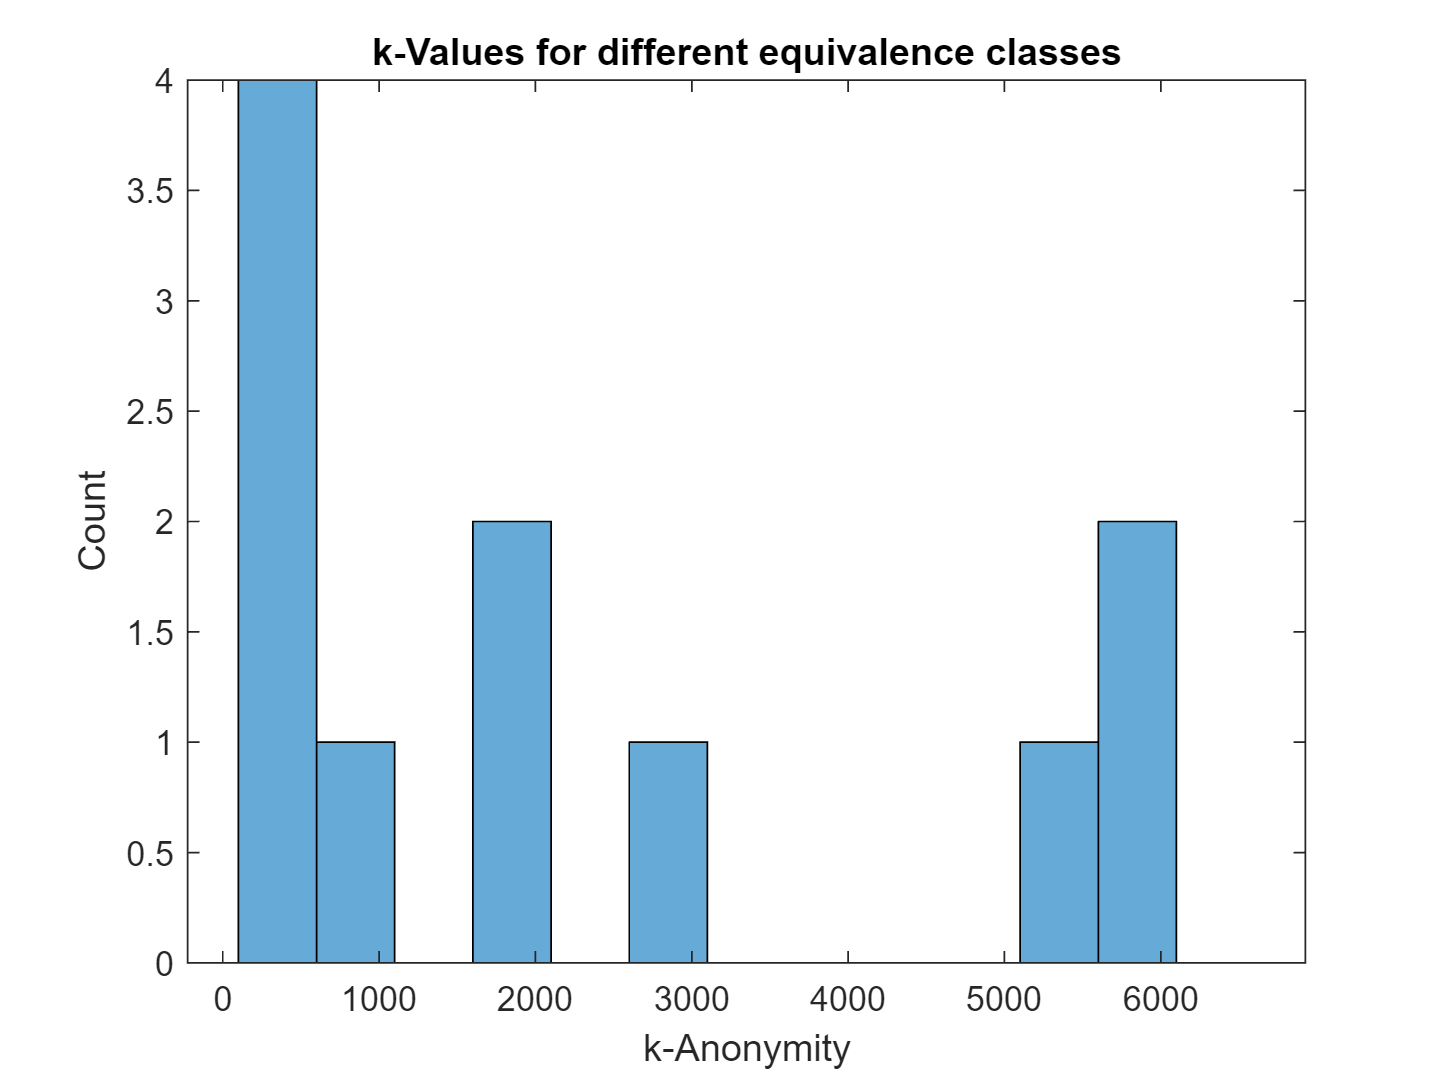

% Plot histogram of the k-Anonymization
eqv_classes_db_g.k;
bins = 100:500:7000;
histogram(eqv_classes_db_g.k, bins);
% and add labels/title
xlabel('k-Anonymity');
ylabel('Count');
title('k-Values for different equivalence classes');

### Entropy l-Diversity and Distinct l-Diversity

% entropy l-diversity and distinct l-diversity on the ORIGINAL table
[db_entropy_l, db_diversity_l, db_EC_table] = lDiversity_Analyze(T_14D_14C_R, db_quasi_identifiers, 'SPEED')

db_entropy_l = 1.1642

db_diversity_l = 2

db_EC_table = 14×8 table
         MARK             MODEL         CAR_YEAR    ENGINE_POWER    AUTOMATIC          FUEL_TYPE           lEntropy    lDistinct
    ______________    ______________    ________    ____________    _________    ______________________    ________    _________

    {'chevrolet' }    {'agile'     }      2011        {'1,4'}         {'n'}      {'Biodiesel_Ethanol' }     2.1722        11    
    {'citroen'   }    {'c3'        }      2013        {'1,4'}         {'n'}      {0×0 char            }     10.596        13    
    {'fiat'      }    {'palio'     }      2012        {'1'  }         {'n'}      {0×0 char            }      5.999        12    
    {'fiat'      }    {'siena'     }      2010        {'1

% entropy l-diversity and distinct l-diversity on the test_T_14D_14C_R table
[db_entropy_l, db_diversity_l, db_EC_table] = lDiversity_Analyze(test_T_14D_14C_R, db_quasi_identifiers, 'SPEED')

db_entropy_l = 1.1642

db_diversity_l = 2

db_EC_table = 13×8 table
         MARK         MODEL    CAR_YEAR    ENGINE_POWER    AUTOMATIC          FUEL_TYPE           lEntropy    lDistinct
    ______________    _____    ________    ____________    _________    ______________________    ________    _________

    {'chevrolet' }    {'*'}      2016        {'1,4'}         {'n'}      {'Biodiesel_Ethanol' }     2.1722        11    
    {'citroen'   }    {'*'}      2016        {'1,4'}         {'n'}      {0×0 char            }     10.596        13    
    {'fiat'      }    {'*'}      2016        {'1'  }         {'n'}      {0×0 char            }     5.9967        12    
    {'ford'      }    {'*'}      2009        {'1,6'}         {'n'}      {0×0 char            }     7.1

% Generalizing FUEL_TYPE
test2_T_14D_14C_R = test_T_14D_14C_R;
test2_T_14D_14C_R.FUEL_TYPE(:) = {'*'};

% entropy l-diversity and distinct l-diversity on the GENERALIZED table
[db_entropy_l, db_diversity_l, db_EC_table] = lDiversity_Analyze(test2_T_14D_14C_R, db_quasi_identifiers, 'SPEED')

db_entropy_l = 2.1722

db_diversity_l = 8

db_EC_table = 12×8 table
         MARK         MODEL    CAR_YEAR    ENGINE_POWER    AUTOMATIC    FUEL_TYPE    lEntropy    lDistinct
    ______________    _____    ________    ____________    _________    _________    ________    _________

    {'chevrolet' }    {'*'}      2016        {'1,4'}         {'n'}        {'*'}       2.1722        11    
    {'citroen'   }    {'*'}      2016        {'1,4'}         {'n'}        {'*'}       10.596        13    
    {'fiat'      }    {'*'}      2016        {'1'  }         {'n'}        {'*'}       5.9967        12    
    {'ford'      }    {'*'}      2009        {'1,6'}         {'n'}        {'*'}       7.1482        12    
    {'ford'      }    {'*'}      2016        {'1,6'}        

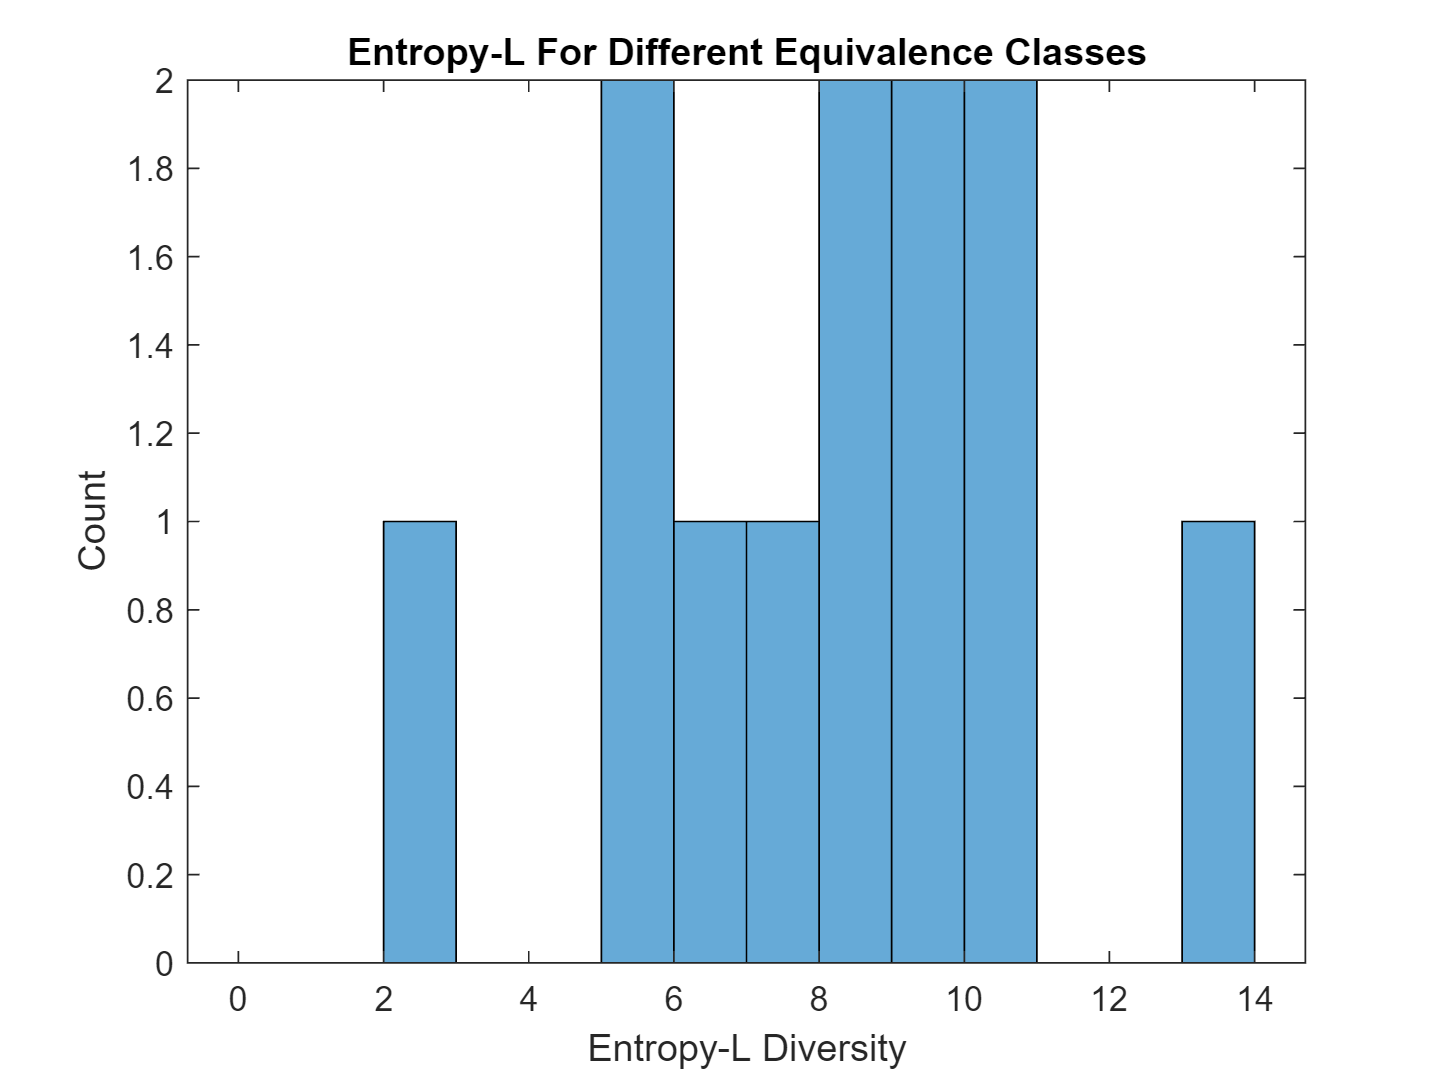

% Histogram For Entropy-L Diversity
bins = 0:1:14;
histogram(db_EC_table.lEntropy, bins);
xlabel('Entropy-L Diversity');
ylabel('Count');
title('Entropy-L For Different Equivalence Classes');

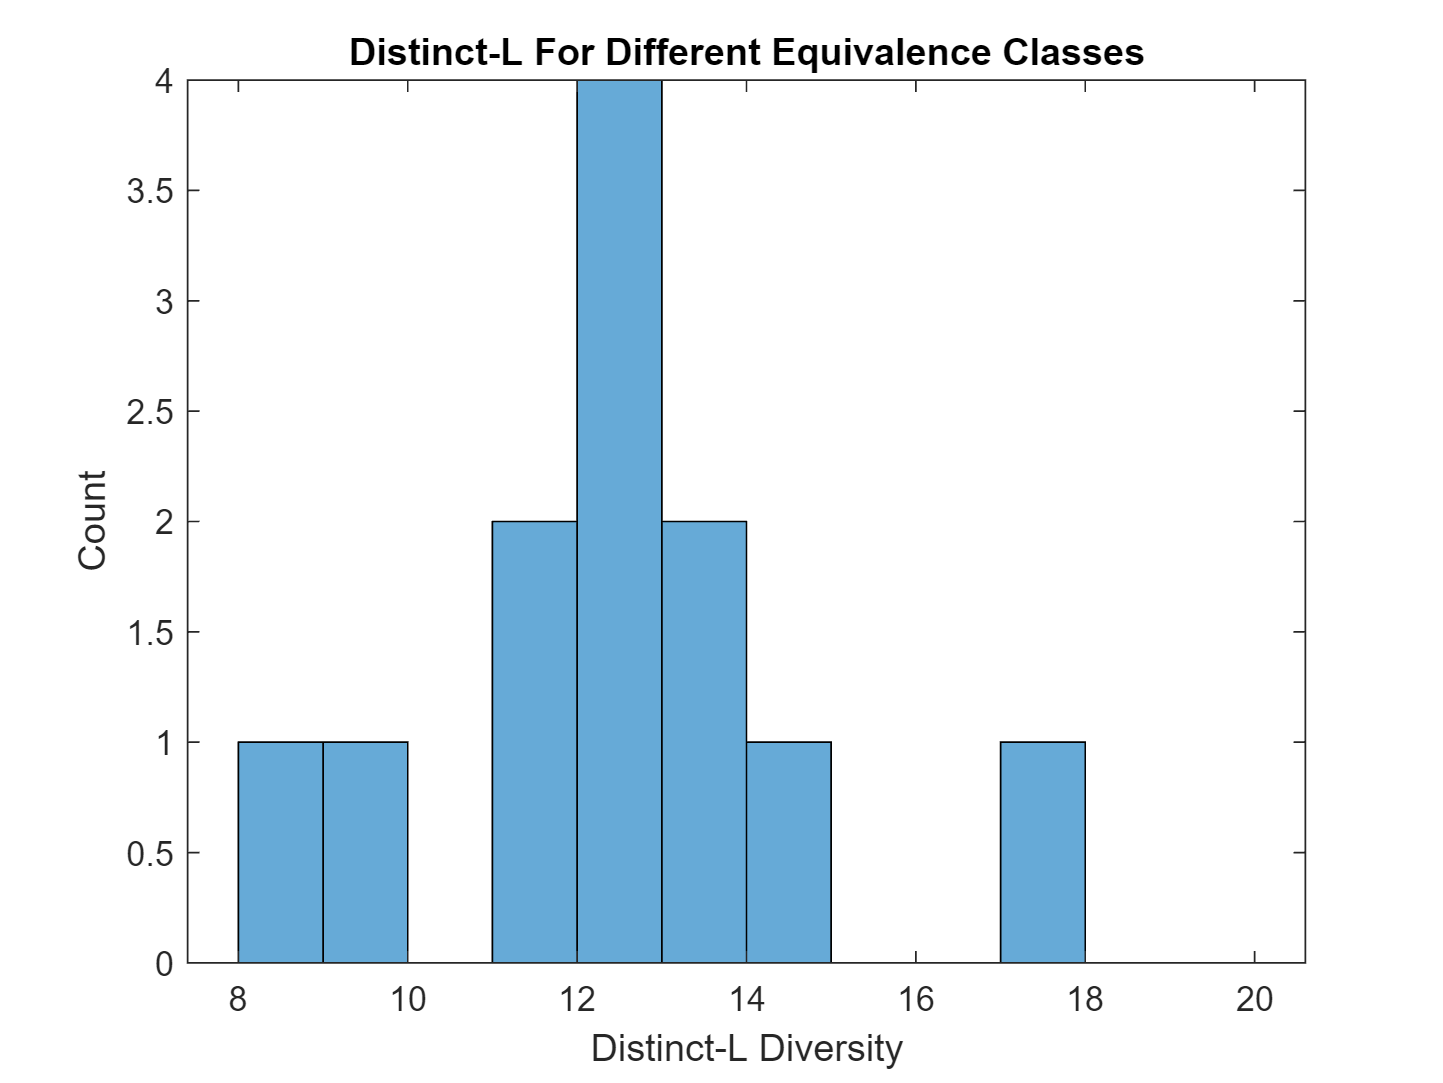

% Histogram For Distinct-L Diversity
bins = 8:1:20;
histogram(db_EC_table.lDistinct, bins);
xlabel('Distinct-L Diversity');
ylabel('Count');
title('Distinct-L For Different Equivalence Classes');

### Delta Presence

qID = {'MARK', 'MODEL', 'CAR_YEAR', 'ENGINE_POWER', 'AUTOMATIC', 'FUEL_TYPE'};
identities = {'VEHICLE_ID','MARK', 'MODEL', 'CAR_YEAR', 'ENGINE_POWER', 'AUTOMATIC', 'FUEL_TYPE'};
private = {'MARK', 'MODEL', 'CAR_YEAR', 'ENGINE_POWER', 'AUTOMATIC', 'FUEL_TYPE','FUEL_LEVEL', 'ENGINE_RPM', 'SPEED', 'ENGINE_RUNTIME','HOURS', 'DAYS_OF_WEEK', 'MONTHS', 'YEAR'};
rows = randperm(size(T_14D_14C_R, 1),10000);

% Delta Presence on the ORIGINAL table
identityTable = T_14D_14C_R(:,identities);
privateTable = T_14D_14C_R(:,private);
[delta_min, delta_max, car_neg, car_pos] = delta_Presence(identityTable, privateTable(rows,:), qID);
fprintf('delta_max=%.4f (Car at risk: %s)\n', delta_max,car_pos );

delta_max=0.2194 (Car at risk: car13)


unique(identityTable(identityTable.VEHICLE_ID == car_pos,:))

ans = 1×7 table
    VEHICLE_ID       MARK        MODEL     CAR_YEAR    ENGINE_POWER    AUTOMATIC    FUEL_TYPE 
    __________    ___________    ______    ________    ____________    _________    __________

    {'car13'}     {'citroen'}    {'c3'}      2013        {'1,4'}         {'n'}      {0×0 char}


fprintf('delta_min=%.4f (Car at risk: %s)\n', delta_min, car_neg);

delta_min=0.1429 (Car at risk: car10)


unique(identityTable(identityTable.VEHICLE_ID == car_neg,:))

ans = 1×7 table
    VEHICLE_ID      MARK        MODEL      CAR_YEAR    ENGINE_POWER    AUTOMATIC    FUEL_TYPE 
    __________    ________    _________    ________    ____________    _________    __________

    {'car10'}     {'fiat'}    {'siena'}      2010         {'1'}          {'n'}      {0×0 char}


% Delta Presence on the GENERALIZED table test
identityTable = test_T_14D_14C_R(:,identities);
privateTable = test_T_14D_14C_R(:,private);
[delta_min, delta_max, car_neg, car_pos] = delta_Presence(identityTable, privateTable(rows,:), qID);
fprintf('delta_max=%.4f (Car at risk: %s)\n', delta_max,car_pos );

delta_max=0.2194 (Car at risk: car13)


unique(identityTable(identityTable.VEHICLE_ID == car_pos,:))

ans = 1×7 table
    VEHICLE_ID       MARK        MODEL    CAR_YEAR    ENGINE_POWER    AUTOMATIC    FUEL_TYPE 
    __________    ___________    _____    ________    ____________    _________    __________

    {'car13'}     {'citroen'}    {'*'}      2016        {'1,4'}         {'n'}      {0×0 char}


fprintf('delta_min=%.4f (Car at risk: %s)\n', delta_min, car_neg);

delta_min=0.1805 (Car at risk: car3)


unique(identityTable(identityTable.VEHICLE_ID == car_neg,:))

ans = 1×7 table
    VEHICLE_ID      MARK       MODEL    CAR_YEAR    ENGINE_POWER    AUTOMATIC    FUEL_TYPE 
    __________    _________    _____    ________    ____________    _________    __________

     {'car3'}     {'honda'}    {'*'}      2009        {'1,4'}         {'n'}      {0×0 char}


% Delta Presence on the GENERALIZED table test2
identityTable = test2_T_14D_14C_R(:,identities);
privateTable = test2_T_14D_14C_R(:,private);
[delta_min, delta_max, car_neg, car_pos] = delta_Presence(identityTable, privateTable(rows,:), qID);
fprintf('delta_max=%.4f (Car at risk: %s)\n', delta_max,car_pos );

delta_max=0.2194 (Car at risk: car13)


unique(identityTable(identityTable.VEHICLE_ID == car_pos,:))

ans = 1×7 table
    VEHICLE_ID       MARK        MODEL    CAR_YEAR    ENGINE_POWER    AUTOMATIC    FUEL_TYPE
    __________    ___________    _____    ________    ____________    _________    _________

    {'car13'}     {'citroen'}    {'*'}      2016        {'1,4'}         {'n'}        {'*'}  


fprintf('delta_min=%.4f (Car at risk: %s)\n', delta_min, car_neg);

delta_min=0.1805 (Car at risk: car3)


unique(identityTable(identityTable.VEHICLE_ID == car_neg,:))

ans = 1×7 table
    VEHICLE_ID      MARK       MODEL    CAR_YEAR    ENGINE_POWER    AUTOMATIC    FUEL_TYPE
    __________    _________    _____    ________    ____________    _________    _________

     {'car3'}     {'honda'}    {'*'}      2009        {'1,4'}         {'n'}        {'*'}  


## Functions

function [k, equivalence_classes] = kAnonymity_Analyze(data_table, quasi_identifiers) 
    quasi_table = data_table(:,quasi_identifiers);
    % ia is the index in unique_table and ic is the index in the U table
    % equivalence_classes = table_quasi(ia) and table_quasi = C(ic).
    [equivalence_classes, ia, iec] = unique(quasi_table, 'rows');
    % Count the number of times each element in C appears in table_quasi
    equivalence_classes.k = accumarray(iec,1);
    k = min(equivalence_classes.k); 
end


% Function for calculating entropy-l diversity and distinct-l divuersity
function [lEntropy, lDistinct, equivalence_classes] = lDiversity_Analyze(data_table, quasi_identifiers, sensitive_column)
    
    % Let's first get the unique rows when the table is projected only on
    % quasi identifiers (each EC).
    equivalence_classes = unique(data_table(:,quasi_identifiers), 'rows');
    
    % initialize variables
    equivalence_classes.lEntropy(:) = NaN; %pre allocate
    equivalence_classes.lDistinct(:) = NaN; %pre allocate
    
    for eqv_class_id = 1:size(equivalence_classes, 1);
        eqv_class = equivalence_classes(eqv_class_id,quasi_identifiers);
        
        % Find which row ids in the original table are part of this EC
        ii = ismember(data_table(:,quasi_identifiers), eqv_class);
        row_ids = all(ii,2); 

        % Vector of sensitive values from the EC
        sensitive_values_from_class = data_table(row_ids, sensitive_column);
        
        % Counts (incidence) of each possible value of the
        % sensitive attribute in the class
        cts=hist(sensitive_values_from_class.(sensitive_column), unique(sensitive_values_from_class.(sensitive_column)));
    
        % lEntropy for this class
        non_zero_cts = cts(cts ~= 0);
        p_values = non_zero_cts ./size(sensitive_values_from_class, 1);
        log_p_calc = -1 .* p_values .* log10(p_values);
        l_entropy = 10^sum(log_p_calc);

        equivalence_classes.lEntropy(eqv_class_id) = l_entropy;
        
        % lDistinct for this class
        l_distinct = size(unique(sensitive_values_from_class), 1);
        equivalence_classes.lDistinct(eqv_class_id) = l_distinct; 
    end
    
    lEntropy = min(equivalence_classes.lEntropy); % TODO: fill this here
    lDistinct = min(equivalence_classes.lDistinct); % TODO: fill this here
end


% Function for calculating delta presence
function delta = delta_Presence_of_Individual(identities, identities_row_id, published_table, quasi_identifiers)
    s = size(identities);
    ident_count = ones(s(1,1),1);
    for q = quasi_identifiers
        ident_count = ident_count & ismember(identities(:,q), identities(identities_row_id,q));
    end

    s = size(published_table);
    ident_count_pub = ones(s(1,1),1);
    for q = quasi_identifiers
        ident_count_pub = ident_count_pub & ismember(published_table(:,q), identities(identities_row_id,q));
    end 
    delta = sum(ident_count_pub) / sum(ident_count);
    % Complete the code here
end

function [delta_min, delta_max, person_at_risk_neg_dis, person_at_risk_pos_dis] = delta_Presence(identities, published_table, quasi_identifiers)
    delta_max = 0;
    delta_min = 1;
    person_at_risk_neg_dis = nan;
    person_at_risk_pos_dis = nan;
    unique_identities = unique(identities);
    for person = 1:length(unique_identities.VEHICLE_ID)
        row_index = find(contains(identities.VEHICLE_ID, unique_identities.VEHICLE_ID(person)));
        temp_d = delta_Presence_of_Individual(identities, row_index(1,:),published_table,quasi_identifiers);
        if(temp_d > delta_max)
            delta_max = temp_d;
            person_at_risk_pos_dis = string(unique_identities.VEHICLE_ID(person));
        end
        if(temp_d < delta_min)
            delta_min = temp_d;
            person_at_risk_neg_dis = string(unique_identities.VEHICLE_ID(person));
        end
    end
    % Complete the code here
end